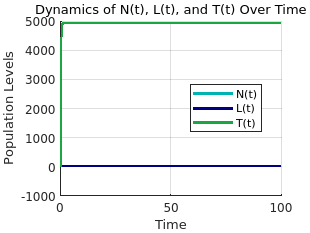

% Nondimensionalized Model

clc; clear; close all;

%% Core Parameters 
P1 = 1;          
q = 1;           
P2 = 1;          
h = 1;           
L = 1;           

%% Tuning Parameters 
T_param1 = 25.7;      
T_param2 = 0.000204;  
beta = 0.00342;       
delta = 1;            
I0 = 1;               

% Initial conditions 
N0 = 1;
L0 = 1;
T0 = 1;
y0 = [N0; L0; T0];

% Time span 
tspan = [0 100];

% Solve using ode45
[t, y] = ode45(@(t, y) systemODEs(t, y, P1, q, P2, L, T_param1, T_param2, beta, delta, h, I0), tspan, y0);

% Extract solutions for N, L, and T
N = y(:,1);
L = y(:,2);
T = y(:,3);

% Plot the results of the system
figure;
hold on;
plot(t, N, 'Color', [0, 0.7, 0.7], 'LineWidth', 2);  
plot(t, L, 'Color', [0, 0, 0.5], 'LineWidth', 2);    
plot(t, T, 'Color', [0.10 0.65 0.25], 'LineWidth', 2); 
hold off;

xlabel('Time');
ylabel('Population Levels');
title('Dynamics of N(t), L(t), and T(t) Over Time', 'FontWeight', 'normal');
legend('N(t)', 'L(t)', 'T(t)', 'Location', 'Best');
grid on;

function dydt = systemODEs(t, y, P1, q, P2, L, T_param1, T_param2, beta, delta, h, I0)
    N = y(1);
    L = y(2);   
    T = y(3);
    
    dNdt = P1 * N * (1 - q * N) - P2 * N - N * T;
    dLdt = N * T + I0 * 2^(-t / h) - L - beta * L * T;
    dTdt = T_param1 * T * (1 - T_param2 * T) - N * T - delta * L * T;
    
    dydt = [dNdt; dLdt; dTdt];
end